# 全交换面积calc  1.1ver

clear,clc
%参数
Lr = 4.1;%辐射管长度
Ws = 3.6;%钢板宽
Wfur = 4.6;%炉宽
epsilon_r = 0.5;%黑度
rho_r = 0.5;%反射率
epsilon_w = 0.85;
rho_w = 0.15;
epsilon_s = 0.75;
rho_s = 0.25;

%序号 直径 段长 h1 h2 辐射管间隔数组 功率数组
cellZoneInfo = {1,0.3,8.7,0.65,0.91,[2700 600 600 600 600 600 1200 600 1200],[115 150 115 150 115 150 115 150 115/2];
         2,0.3,7.2,0.65,0.91,[600 600 600 600 600 600 600 600 600 600 600 600],[115/2 150 115 150 115 150 115 150 115 150 115 150 95/2];
         3,0.28,7.2,0.66,0.92,[600 600 600 600 600 600 1200 600 1200 600],[95/2 120 95 120 95 120 95 120 95 120 95/2];
         4,0.28,7.2,0.66,0.92,[600 2400 600 600 1200 600 600 600],[95/2 120 95 120 95 120 95 120 95/2];
         5,0.28,7.2,0.66,0.92,[600 1200 600 1200 600 1200 600 1200],[95/2 120 95 120 95 120 95 120 95/2];
         6,0.28,7.2,0.66,0.92,[1200 1200 1200 1200 1200 1200],[95/2 120 95 120 95 120 95/2];
         7,0.28,6.6,0.66,0.92,[1200 2400 1800 1200],[95/2 120 95 120 95/2];
         8,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[95/2 80 55 80 55/2];
         9,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         10,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         11,0.208,9.3,0.696,0.956,[1800 1800 1800 1800 2100],[55/2 80 55 120 95];}

cellZoneInfo = 11×7 cell 数组
    {[ 1]}    {[0.3000]}    {[8.7000]}    {[0.6500]}    {[0.9100]}    {[         2700 600 600 600 600 600 1200 600 1200]}    {[                    115 150 115 150 115 150 115 150 57.5000]}
    {[ 2]}    {[0.3000]}    {[7.2000]}    {[0.6500]}    {[0.9100]}    {[600 600 600 600 600 600 600 600 600 600 600 600]}    {[57.5000 150 115 150 115 150 115 150 115 150 115 150 47.5000]}
    {[ 3]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[      600 600 600 600 600 600 1200 600 1200 600]}    {[            47.5000 120 95 120 95 120 95 120 95 120 47.5000]}
    {[ 4]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[              600 2400 600 600 1200 600 600 600]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 5]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[            600 1200 600 1200 600 1200 600 1200]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 6]}    {[0.2800]}   


SR = zeros(1,length(cellZoneInfo));
SW = zeros(1,length(cellZoneInfo));
WR = zeros(1,length(cellZoneInfo));


for i = 1:length(cellZoneInfo)

    %计算
    S = cellZoneInfo{i,6}./1000;%辐射管间隔数组
    d = cellZoneInfo{i,2};%辐射管直径
    L = cellZoneInfo{i,3};%段长
    h1 = cellZoneInfo{i,4};%见函数
    h2 = cellZoneInfo{i,5};
    kr = Lr/Wfur;%辐射管长度系数
    ks = Ws/Wfur;%钢板宽度系数

    xrp = zeros(1,length(S));
    for j = 1:length(S)
        if S(j) == 2.7 || S(j) == 2.1
            xrp(j) = (d/2)/S(j)*atan(S(j)/(d/2));
        else
            xrp(j) = S(j)/(pi*d)*(1+d/S(j)*acos(d/S(j))-(1-(d/S(j))^2)^(1/2));
        end
    end
    %加权辐射管对假想面角系数
    Xrp = 0;
    for j = 1:length(xrp)
        Xrp = Xrp+S(j)/L*xrp(j);
    end
    %角系数

    Xp1w2 = phi_p1_w2(Wfur,L,h1);
    Xp2s = phi_p2_s(Wfur,L,h2);
    Xp2w1 = phi_p2_w1(Wfur,L,h2);

    Xrs = Xrp * 1/kr * Xp2s * ks;
    Xrw = Xrp * 1/kr *Xp1w2 + Xrp * 1/kr *Xp2w1;
    Xrr = 1 - Xrs - Xrw;

    Fs = L*Ws;
    Fw = L*Wfur+L*h1*2+L*h2*2;
    Fr = pi*d*length(S)*Lr;

    Xss= 0;
    Xsr = Xrs * Fr/Fs;
    Xsw = 1 - Xsr - Xss;
    Xwr = Xrw * Fr/Fw;
    Xws = Xsw * Fs/Fw;
    Xww = 1 - Xwr - Xws;
    %直接交换面积
    rr = Fr * Xrr;
    rw = Fr * Xrw;
    rs = Fr * Xrs;
    wr = Fw * Xwr;
    ww = Fw * Xww;
    ws = Fw * Xws;
    sr = Fs * Xsr;
    sw = Fs * Xsw;
    ss = Fs * Xss;

    %全交换面积

    SR(i) = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr);
    SW(i) = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww);
    WR(i) = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww);

end
RS = SR

RS =     3.9019    5.8765    4.7038    3.8445    3.8452    2.9456    1.9797    1.4860    1.4860    1.4860    1.6826


WS = SW

WS =    18.1218   12.0263   13.2786   14.1956   14.1945   15.1569   14.6709   16.7417   16.7417   16.7417   21.9265


RW = WR

RW =     8.1940   12.2397    9.8812    8.1103    8.1119    6.2416    4.2266    3.2041    3.2041    3.2041    3.6008


SR

SR =     3.9019    5.8765    4.7038    3.8445    3.8452    2.9456    1.9797    1.4860    1.4860    1.4860    1.6826


SW

SW =    18.1218   12.0263   13.2786   14.1956   14.1945   15.1569   14.6709   16.7417   16.7417   16.7417   21.9265


WR

WR =     8.1940   12.2397    9.8812    8.1103    8.1119    6.2416    4.2266    3.2041    3.2041    3.2041    3.6008


# 三元法calc   ver1.1

%初(xia)始(gei)化温度
Tw_init = [700 720 740 760 780 800 820 840 860 870 870] + 273.15;
Ts_1_init = [150 250 420 555 666 777 820 835 850 870 870] + 273.15;
Tw_zone = zeros(1,length(cellZoneInfo));
Tr_zone = zeros(1,length(cellZoneInfo));
Ts_zone = zeros(1,length(cellZoneInfo));


Lfur = 82.2;%炉长,m
ths = 50/1000;%板厚,m
Time_heat = 80 * 60;%加热时间,s
Vs = Lfur / Time_heat;%物料速度
Thw = 0.3;%炉墙厚度
lambda_w = 0.138*250/300+0.15*50/300;%炉墙导热系数
hw = 10;%炉墙自然对流换热系数
Temp_out = 30+273.15;%环境温度,k
density_s = 7860;
Cs = 0.565*1000;%比热容
lambda_s = 45;
sigma = 5.67*10^(-8);%斯忒藩-玻尔兹曼常数
N = 10;%层数
timeStep = 800;%时间步长节点数
Ts_2 = 0;%初始化，进循环用
phi_r = zeros(1,length(cellZoneInfo));

Temp_inlet = zeros(N+1,length(cellZoneInfo));
Temp_inlet(:,1) = 30 + 273.15;
Temp_total = zeros(length(cellZoneInfo),timeStep*length(cellZoneInfo));

for i = 1:length(cellZoneInfo)

    phi_r(i) = sum(cellZoneInfo{i,7})*1000;%W
    Tw = Tw_init(i);
    Ts_1 = Ts_1_init(i);%段内物料表面初始温度
    L = cellZoneInfo{i,3};%段长
    Time_zone = L / Vs;%段内时间

    %能量平衡解Tr
    while(abs((Ts_2 - Ts_1)/Ts_1)>=0.001)
        syms Tr;
        f1 = sigma*RW(i)*(Tr^4 - Tw^4) + sigma*RS(i)*(Tr^4 - Ts_1^4) == phi_r(i);
        Tr = solve(f1,Tr);
        Tr = vpa(Tr);
        Tr= Tr(imag(Tr) == 0 & real(Tr) > 0);
    %能量平衡解Tw   
        syms Tw;
        f2 = sigma*SW(i)*(Ts_1^4 - Tw^4) + sigma*RW(i)*(Tr^4 - Tw^4) == Fw*(Tw - Temp_out)/(1/hw+Thw/lambda_w);
        Tw = solve(f2,Tw);
        Tw = vpa(Tw);
        Tw= Tw(imag(Tw) == 0 & real(Tw) > 0);
        
        qcon = -(sigma*RS(i)*(Ts_1^4 - Tr^4) + sigma*WS(i)*(Ts_1^4 - Tw^4))/Fs;%钢坯表面热流密度
    %差分求物料温度    
        T = Temp_inlet(:,i);
        delta_t = Time_zone / timeStep;%时间步长
        delta_x = ths/(2*N);%空间步长
        Temp_zone = zeros(length(cellZoneInfo),timeStep);
        for j = 1:timeStep
            T = TDMA(qcon,N,density_s,delta_t,delta_x,T);
            Temp_zone(:,j) = T;
        end
    
        Ts_2 = sum(Temp_zone(1,:))/timeStep;%热流反算物料表面温度
    
        % if abs((Ts_2 - Ts_1)/Ts_1)<=0.001
        %     break;
        % end
    
        Ts_1 = Ts_2;
    end
    Temp_inlet(:,i+1) = T
    Tw_zone(i) = Tw ;%K
    Tr_zone(i) = Tr ;%K
    Ts_zone(i) = Ts_2 ;%K
    Temp_total(:,1+(i-1)*timeStep:i*timeStep) = Temp_zone;%K

end

Temp_inlet =   303.1500  488.2782         0         0         0         0         0         0         0         0         0
  303.1500  486.2454         0         0         0         0         0         0         0         0         0
  303.1500  484.4324         0         0         0         0         0         0         0         0         0
  303.1500  482.8372         0         0         0         0         0         0         0         0         0
  303.1500  481.4582         0         0         0         0         0         0         0         0         0
  303.1500  480.2937         0         0         0         0         0         0         0         0         0
  303.1500  479.3427         0         0         0         0         0         0         0         0         0
  303.1500  478.6040         0         0         0         0         0         0         0         0         0
  303.1500  478.0770         0         0         0         0         0         0         0         

Temp_inlet =   303.1500  488.2782  656.8720         0         0         0         0         0         0         0         0
  303.1500  486.2454  653.9941         0         0         0         0         0         0         0         0
  303.1500  484.4324  651.4308         0         0         0         0         0         0         0         0
  303.1500  482.8372  649.1781         0         0         0         0         0         0         0         0
  303.1500  481.4582  647.2325         0         0         0         0         0         0         0         0
  303.1500  480.2937  645.5912         0         0         0         0         0         0         0         0
  303.1500  479.3427  644.2517         0         0         0         0         0         0         0         0
  303.1500  478.6040  643.2118         0         0         0         0         0         0         0         0
  303.1500  478.0770  642.4702         0         0         0         0         0         0         

Temp_inlet =   303.1500  488.2782  656.8720  768.0689         0         0         0         0         0         0         0
  303.1500  486.2454  653.9941  765.6375         0         0         0         0         0         0         0
  303.1500  484.4324  651.4308  763.4766         0         0         0         0         0         0         0
  303.1500  482.8372  649.1781  761.5814         0         0         0         0         0         0         0
  303.1500  481.4582  647.2325  759.9473         0         0         0         0         0         0         0
  303.1500  480.2937  645.5912  758.5707         0         0         0         0         0         0         0
  303.1500  479.3427  644.2517  757.4485         0         0         0         0         0         0         0
  303.1500  478.6040  643.2118  756.5782         0         0         0         0         0         0         0
  303.1500  478.0770  642.4702  755.9580         0         0         0         0         0         

Temp_inlet =   303.1500  488.2782  656.8720  768.0689  848.8378         0         0         0         0         0         0
  303.1500  486.2454  653.9941  765.6375  846.7061         0         0         0         0         0         0
  303.1500  484.4324  651.4308  763.4766  844.8050         0         0         0         0         0         0
  303.1500  482.8372  649.1781  761.5814  843.1326         0         0         0         0         0         0
  303.1500  481.4582  647.2325  759.9473  841.6869         0         0         0         0         0         0
  303.1500  480.2937  645.5912  758.5707  840.4662         0         0         0         0         0         0
  303.1500  479.3427  644.2517  757.4485  839.4694         0         0         0         0         0         0
  303.1500  478.6040  643.2118  756.5782  838.6952         0         0         0         0         0         0
  303.1500  478.0770  642.4702  755.9580  838.1428         0         0         0         0         

Temp_inlet =   303.1500  488.2782  656.8720  768.0689  848.8378  920.7374         0         0         0         0         0
  303.1500  486.2454  653.9941  765.6375  846.7061  918.6944         0         0         0         0         0
  303.1500  484.4324  651.4308  763.4766  844.8050  916.8659         0         0         0         0         0
  303.1500  482.8372  649.1781  761.5814  843.1326  915.2519         0         0         0         0         0
  303.1500  481.4582  647.2325  759.9473  841.6869  913.8527         0         0         0         0         0
  303.1500  480.2937  645.5912  758.5707  840.4662  912.6685         0         0         0         0         0
  303.1500  479.3427  644.2517  757.4485  839.4694  911.6994         0         0         0         0         0
  303.1500  478.6040  643.2118  756.5782  838.6952  910.9455         0         0         0         0         0
  303.1500  478.0770  642.4702  755.9580  838.1428  910.4069         0         0         0         

Temp_inlet =   303.1500  488.2782  656.8720  768.0689  848.8378  920.7374  966.4579         0         0         0         0
  303.1500  486.2454  653.9941  765.6375  846.7061  918.6944  965.0952         0         0         0         0
  303.1500  484.4324  651.4308  763.4766  844.8050  916.8659  963.8757         0         0         0         0
  303.1500  482.8372  649.1781  761.5814  843.1326  915.2519  962.7994         0         0         0         0
  303.1500  481.4582  647.2325  759.9473  841.6869  913.8527  961.8664         0         0         0         0
  303.1500  480.2937  645.5912  758.5707  840.4662  912.6685  961.0768         0         0         0         0
  303.1500  479.3427  644.2517  757.4485  839.4694  911.6994  960.4307         0         0         0         0
  303.1500  478.6040  643.2118  756.5782  838.6952  910.9455  959.9281         0         0         0         0
  303.1500  478.0770  642.4702  755.9580  838.1428  910.4069  959.5691         0         0         

Temp_inlet =   303.1500  488.2782  656.8720  768.0689  848.8378  920.7374  966.4579  993.3549         0         0         0
  303.1500  486.2454  653.9941  765.6375  846.7061  918.6944  965.0952  992.4749         0         0         0
  303.1500  484.4324  651.4308  763.4766  844.8050  916.8659  963.8757  991.6874         0         0         0
  303.1500  482.8372  649.1781  761.5814  843.1326  915.2519  962.7994  990.9925         0         0         0
  303.1500  481.4582  647.2325  759.9473  841.6869  913.8527  961.8664  990.3901         0         0         0
  303.1500  480.2937  645.5912  758.5707  840.4662  912.6685  961.0768  989.8804         0         0         0
  303.1500  479.3427  644.2517  757.4485  839.4694  911.6994  960.4307  989.4632         0         0         0
  303.1500  478.6040  643.2118  756.5782  838.6952  910.9455  959.9281  989.1388         0         0         0
  303.1500  478.0770  642.4702  755.9580  838.1428  910.4069  959.5691  988.9071         0         

Temp_inlet = 1.0e+03 *

    0.3031    0.4883    0.6569    0.7681    0.8488    0.9207    0.9665    0.9934    1.0142         0         0
    0.3031    0.4862    0.6540    0.7656    0.8467    0.9187    0.9651    0.9925    1.0136         0         0
    0.3031    0.4844    0.6514    0.7635    0.8448    0.9169    0.9639    0.9917    1.0130         0         0
    0.3031    0.4828    0.6492    0.7616    0.8431    0.9153    0.9628    0.9910    1.0126         0         0
    0.3031    0.4815    0.6472    0.7599    0.8417    0.9139    0.9619    0.9904    1.0121         0         0
    0.3031    0.4803    0.6456    0.7586    0.8405    0.9127    0.9611    0.9899    1.0118         0         0
    0.3031    0.4793    0.6443    0.7574    0.8395    0.9117    0.9604    0.9895    1.0115         0         0
    0.3031    0.4786    0.6432    0.7566    0.8387    0.9109    0.9599    0.9891    1.0113         0         0
    0.3031    0.4781    0.6425    0.7560    0.8381    0.9104    0.9596    0.9889    1.01

Temp_inlet = 1.0e+03 *

    0.3031    0.4883    0.6569    0.7681    0.8488    0.9207    0.9665    0.9934    1.0142    1.0346         0
    0.3031    0.4862    0.6540    0.7656    0.8467    0.9187    0.9651    0.9925    1.0136    1.0341         0
    0.3031    0.4844    0.6514    0.7635    0.8448    0.9169    0.9639    0.9917    1.0130    1.0336         0
    0.3031    0.4828    0.6492    0.7616    0.8431    0.9153    0.9628    0.9910    1.0126    1.0331         0
    0.3031    0.4815    0.6472    0.7599    0.8417    0.9139    0.9619    0.9904    1.0121    1.0327         0
    0.3031    0.4803    0.6456    0.7586    0.8405    0.9127    0.9611    0.9899    1.0118    1.0324         0
    0.3031    0.4793    0.6443    0.7574    0.8395    0.9117    0.9604    0.9895    1.0115    1.0321         0
    0.3031    0.4786    0.6432    0.7566    0.8387    0.9109    0.9599    0.9891    1.0113    1.0319         0
    0.3031    0.4781    0.6425    0.7560    0.8381    0.9104    0.9596    0.9889    1.01

Temp_inlet = 1.0e+03 *

    0.3031    0.4883    0.6569    0.7681    0.8488    0.9207    0.9665    0.9934    1.0142    1.0346    1.0542
    0.3031    0.4862    0.6540    0.7656    0.8467    0.9187    0.9651    0.9925    1.0136    1.0341    1.0537
    0.3031    0.4844    0.6514    0.7635    0.8448    0.9169    0.9639    0.9917    1.0130    1.0336    1.0532
    0.3031    0.4828    0.6492    0.7616    0.8431    0.9153    0.9628    0.9910    1.0126    1.0331    1.0528
    0.3031    0.4815    0.6472    0.7599    0.8417    0.9139    0.9619    0.9904    1.0121    1.0327    1.0524
    0.3031    0.4803    0.6456    0.7586    0.8405    0.9127    0.9611    0.9899    1.0118    1.0324    1.0521
    0.3031    0.4793    0.6443    0.7574    0.8395    0.9117    0.9604    0.9895    1.0115    1.0321    1.0518
    0.3031    0.4786    0.6432    0.7566    0.8387    0.9109    0.9599    0.9891    1.0113    1.0319    1.0516
    0.3031    0.4781    0.6425    0.7560    0.8381    0.9104    0.9596    0.9889    1.01

Temp_inlet = 1.0e+03 *

    0.3031    0.4883    0.6569    0.7681    0.8488    0.9207    0.9665    0.9934    1.0142    1.0346    1.0542    1.0923
    0.3031    0.4862    0.6540    0.7656    0.8467    0.9187    0.9651    0.9925    1.0136    1.0341    1.0537    1.0915
    0.3031    0.4844    0.6514    0.7635    0.8448    0.9169    0.9639    0.9917    1.0130    1.0336    1.0532    1.0908
    0.3031    0.4828    0.6492    0.7616    0.8431    0.9153    0.9628    0.9910    1.0126    1.0331    1.0528    1.0902
    0.3031    0.4815    0.6472    0.7599    0.8417    0.9139    0.9619    0.9904    1.0121    1.0327    1.0524    1.0897
    0.3031    0.4803    0.6456    0.7586    0.8405    0.9127    0.9611    0.9899    1.0118    1.0324    1.0521    1.0892
    0.3031    0.4793    0.6443    0.7574    0.8395    0.9117    0.9604    0.9895    1.0115    1.0321    1.0518    1.0888
    0.3031    0.4786    0.6432    0.7566    0.8387    0.9109    0.9599    0.9891    1.0113    1.0319    1.0516    1.0885
    0.30

Tw_zone - 273.15%各段温度

ans =   644.2486  760.0091  728.3133  745.8370  800.9128  847.4872  864.6127  862.2805  874.7420  892.4426  895.5944


Tr_zone - 273.15

ans = 1.0e+03 *

    0.9512    0.9475    0.9290    0.9438    0.9654    0.9879    1.0027    0.9988    1.0022    1.0114    1.0394


Ts_zone - 273.15

ans =   126.6182  301.6818  439.1833  534.9368  611.5335  669.3350  705.9621  730.1876  751.2264  771.2649  800.5884


Temp_zone(1,timeStep) - 273.15 %物料出炉温度

ans = 819.1651

Temp_total = Temp_total -273.15%钢温温度场

Temp_total =    34.5887   32.5264   35.4175   34.2132   36.1190   35.4842   36.7838   36.5066   37.4262   37.3681   38.0474   38.1207   38.6467   38.7973   39.2248   39.4198   39.7833   40.0028   40.3244   40.5566   40.8505   41.0887   41.3638   41.6042   41.8666   42.1072   42.3607   42.6005   42.8477   43.0863   43.3290   43.5662   43.8057   44.0416   44.2787   44.5134   44.7487   44.9824   45.2163   45.4492   45.6821   45.9142   46.1463   46.3778   46.6092   46.8403   47.0712   47.3019   47.5324   47.7627
   31.9312   31.8497   33.1012   33.1422   34.0294   34.1698   34.8364   35.0391   35.5657   35.8034   36.2388   36.4937   36.8684   37.1300   37.4636   37.7260   38.0312   38.2915   38.5768   38.8335   39.1046   39.3574   39.6182   39.8671   40.1204   40.3659   40.6136   40.8561   41.0995   41.3394   41.5796   41.8175   42.0552   42.2913   42.5271   42.7618   42.9961   43.2297   43.4628   43.6954   43.9277   44.1595   44.3911   44.6223   44.8533   45.0840   45.3145   45.5448   45.

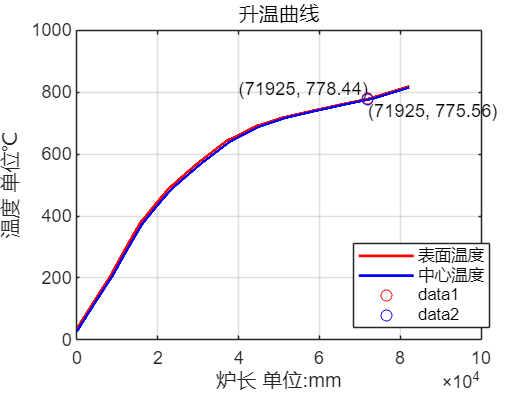






% 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
process_vector = [cellZoneInfo{:,3}] * 1000;

% 初始化 x 坐标和 y 坐标
x_total = [];
y1_total = [];
y11_total = [];

% 累积和计算 x 坐标
x_start = 0;
for i = 1:length(cellZoneInfo)
    % 计算当前区间的 x 坐标
    x_end = x_start + process_vector(i);
    x = linspace(x_start, x_end, timeStep);
    x_total = [x_total, x];
    
    % 创建当前区间的矩阵 11x800
    matrix = Temp_total(:, 1 + (i-1) * timeStep : i * timeStep);
    
    % 提取第一行和最后一行
    y1 = matrix(1, :);
    y11 = matrix(11, :);
    
    % 累积 y 坐标
    y1_total = [y1_total, y1];
    y11_total = [y11_total, y11];
    
    % 更新 x 起点
    x_start = x_end;
end

% 绘制折线图
figure;
plot(x_total, y1_total, 'r-', 'LineWidth', 1.5); % 第一行用红色绘制
hold on;
plot(x_total, y11_total, 'b-', 'LineWidth', 1.5); % 最后一行用蓝色绘制

% 添加图例和标签
legend('表面温度', '中心温度');
xlabel('炉长 单位:mm');
ylabel('温度 单位℃');
title('升温曲线');

% 显示网格
grid on;

% 查找 x = 71925 对应的 y 值
x_target = 71925;
[~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引
y1_target = y1_total(idx);
y11_target = y11_total(idx);

% 在图中标注 x = 71925 时对应的 y 值
plot(x_target, y1_target, 'ro'); % 在表面温度曲线上的标注
text(x_target, y1_target, sprintf('(%d, %.2f)', x_target, y1_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

plot(x_target, y11_target, 'bo'); % 在中心温度曲线上的标注
text(x_target, y11_target, sprintf('(%d, %.2f)', x_target, y11_target), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');

hold off;

**函数**

%计算空间角系数
%x为炉宽，m;h为炉高，m;y为炉段长度，m;h1为辐射管上端距炉墙高度，m;h2为辐射管下端距假象面p高度，m
function phi = phi_p1_w2(x, y, h1)
    X = x / h1;
    Y = y / h1;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_s(x, y, h2)
    X = x / h2;
    Y = y / h2;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_w1(x, y, h2)
    H = h2 / y;
    W = x / y;
    
    term1 = W * atan(1 / W) + H * atan(1 / H);
    term2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    term3 = (1 + W^2) * (1 + H^2) / (1 + W^2 + H^2) * (W^2 * (1 + W^2 + H^2) / ((1 + W^2) * (W^2 + H^2)))^(W^2);
    term4 = (H^2 * (1 + H^2 + W^2) / ((1 + H^2) * (H^2 + W^2)))^(H^2);
    phi = (2 / (pi * W)) * (term1 - term2 + 1/4*log(term3 * term4));
end

function phi = phi_p2_w11(x, y, h2)
    % 定义H和W
    H = h2 / y;
    W = x / y;
    
    % 计算第一部分
    part1 = W * atan(1 / W) + H * atan(1 / H);
    
    % 计算第二部分
    part2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    
    % 计算第三部分中的内部分数
    term1_numerator = (1 + W^2) * (1 + H^2);
    term1_denominator = 1 + W^2 + H^2;
    term1 = term1_numerator / term1_denominator;
    
    term2_numerator = W^2 * (1 + W^2 + H^2);
    term2_denominator = (1 + W^2) * (W^2 + H^2);
    term2 = term2_numerator / term2_denominator;
    term2 = term2^(W^2);
    
    term3_numerator = H^2 * (1 + H^2 + W^2);
    term3_denominator = (1 + H^2) * (H^2 + W^2);
    term3 = term3_numerator / term3_denominator;
    term3 = term3^(H^2);
    
    % 计算第三部分
    part3 = (1/4) * log(term1 * term2 * term3);
    
    % 计算最终结果
    phi = (2 / (pi * W)) * (part1 - part2 + part3);
    
end

%全交换面积计算

function SR = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr)
    % 计算 SR
    numerator = -Fr * epsilon_r * Fs * epsilon_s * (-Fw * rho_w * Xwr * Xws + Fs * Xsr * (-1 + rho_w * Xww));
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SR = numerator / denominator;
end

function SW = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww)
    % 计算 SW
    numerator = Fw * epsilon_w * Fs * epsilon_s * (Fs * rho_r * Xsr * Xwr + Fr * (1 - rho_r * Xrr) * Xws);
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SW = numerator / denominator;
end

function WR = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww)
    % 计算 WR
    numerator = Fr * epsilon_r * Fw * epsilon_w * (Fs * rho_s * Xsr * Xsw + Fw * Xwr);
    denominator = -Fr * (-1 + rho_r * Xrr) * (Fs * rho_s * rho_w * Xsw^2 + Fw * (-1 + rho_w * Xww)) ...
                  + Fw * rho_r * (Fw * rho_w * Xwr^2 + Fs * rho_s * Xsr * (Xsr + 2 * rho_w * Xsw * Xwr - rho_w * Xsr * Xww));
    WR = -numerator / denominator;
end

%TDMA求解全隐式差分
%热流 离散层数 密度 时间步长 空间步长 上一时刻温度场
function T = TDMA(Qcon,N,density,delta_t,delta_x,T)
    %初始化
    Cp_point = zeros(1,N+1);
    Lambda_point = zeros(1,N+1);

    for i = 1 : N+1
        [Cp_point(i) , Lambda_point(i)] = calPhysicalParameters(1 , T(i));
    end
    Cp_layer = computeAdjacentAverages(Cp_point);
    Lambda_Layer = computeAdjacentHarmonicAverages(Lambda_point);
    Fo = Lambda_Layer./(density.*Cp_layer)*delta_t/(delta_x^2);
    T(1) = T(1) + 2*Fo(1)*(T(2) - T(1) + Qcon*delta_x/Lambda_Layer(1));
    T(N+1) = T(N+1) + 2*Fo(N)*(T(N) - T(N+1));
    a = -Fo(2:N-1);
    b = 1 + computeAdjacentSums(Fo);
    c = -Fo(2:N-1);
    d = T(2:N);
    d(1) = d(1) + Fo(1) * T(1);
    d(N-1) = d(N-1) + Fo(N) * T(N+1);
    
    x = tridiagonal_vector(a,b,c,d);%三对角矩阵算法
    % 检查向量长度以确保可以替换
    if length(T) < 2 || length(x) ~= length(T) - 2
        error('向量 T 和 x 的长度不匹配，无法进行替换');
    end
    % 替换 T 的第 2 到第 N 个元素为 x 的第 1 到第 N-1 个元素
    T(2:end-1) = x;
end


%计算相邻两元素的算术平均值
function avgArray = computeAdjacentAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    avgArray = zeros(1, n-1);

    % 计算相邻元素的算术平均值
    for i = 1:n-1
        avgArray(i) = (inputArray(i) + inputArray(i+1)) / 2;
    end
end


%计算相邻两元素的调和平均值
function harmonicAvgArray = computeAdjacentHarmonicAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的调和平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    harmonicAvgArray = zeros(1, n-1);

    % 计算相邻元素的调和平均值
    for i = 1:n-1
        harmonicAvgArray(i) = 2 / (1/inputArray(i) + 1/inputArray(i+1));
    end
end

%计算两相邻元素的加和
function sumArray = computeAdjacentSums(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的和
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    sumArray = zeros(1, n-1);

    % 计算相邻元素的和
    for i = 1:n-1
        sumArray(i) = inputArray(i) + inputArray(i+1);
    end
end


